## Tutorial on the downsampling, metrics and noises

**Recap from last week:**

Get the general settings (data path, source code path, generated report path)

run("CIRLSetup.m")

HR settings of a 200x200x200 Bead for the 3-slit Tunable system

run("SimTunableBead200Setup.m")

HR point spread function

h  = PSFAgard(Settings);

XY = 200

Z = 200

dXY = 0.0250

dZ = 0.0250

HR modulating pattern

[im, jm, ~] = PatternTunable3DNSlits(Settings);

HR bead object construction

Settings.Radius    = 2/2;
Settings.Thickness = 1/2;
ob        = SphericalShell(Settings);

HR forward images

gHR  = ForwardModel(ob, h, im, jm);

**This week:**

**Downsampling**

1. Get the size of the forward image:

[X, Y, Z, ~, ~] = size(gHR)

X = 200

Y = 200

Z = 200

List the orientations:

theta

theta =      0    60   120


List the phases:

phi

phi =      0   120   240


2. Get the forward image of the orientation 60 and the phase 0:

gHR_60_0 = gHR(:,:,:,2,1);

3. Plot the forward image g_60_0 above:

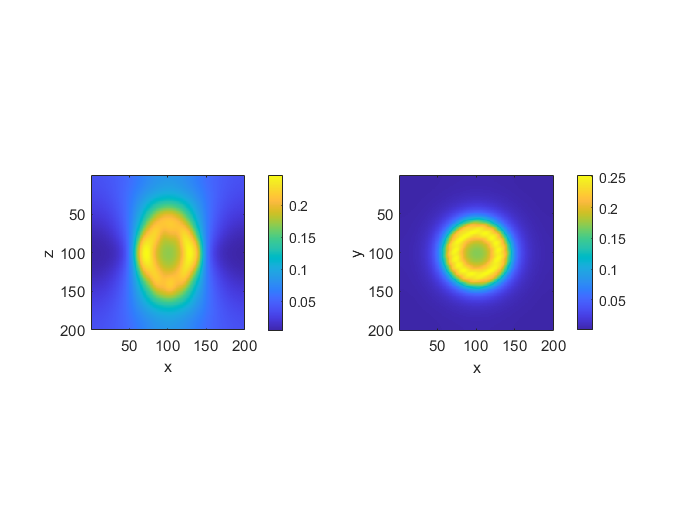

figure;
subplot(1,2,1); imagesc(squeeze(gHR_60_0(1+Y/2,:,:))');
axis square; xlabel('x'); ylabel('z'); colorbar; 
subplot(1,2,2); imagesc(gHR_60_0(:,:,1 + Z/2));
axis square; xlabel('x'); ylabel('y'); colorbar; 

4. Downsampling the forward image g_60_0 by taking the **odd indeces**:

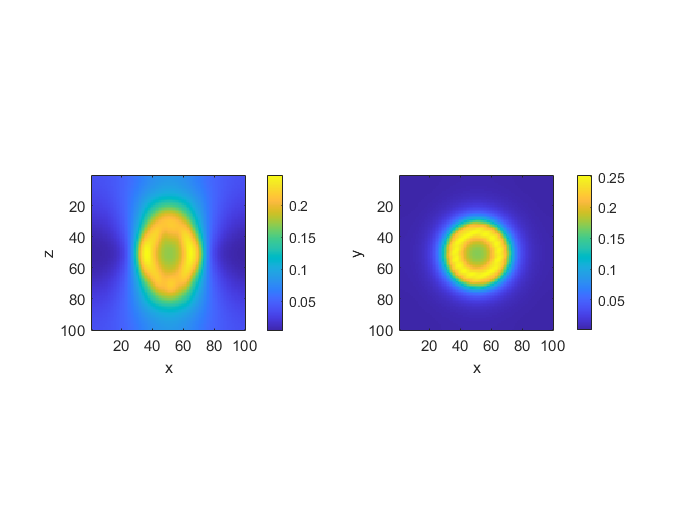

gOdd_60_0 = gHR_60_0(1:2:end, 1:2:end, 1:2:end);
halfZ = Z/2;
halfX = X/2;
figure;
subplot(1,2,1); imagesc(squeeze(gOdd_60_0(1 + halfX/2,:,:))');
axis square; xlabel('x'); ylabel('z'); colorbar; 
subplot(1,2,2); imagesc(gOdd_60_0(:,:,1 + halfZ/2));
axis square; xlabel('x'); ylabel('y'); colorbar; 

5. (**question**) What are the differences between the 2 pictures above in 3 and 4?

Answer: ...

6. (**exercises**) Please do the downsampling of the forward image g_60_0 by taking the **even indeces** and plot xy, xz pictures for it.

gEven_60_0 = ...
figure;
...

Is there any difference between the picture in 4. and this picture?

Answer: ...

7. Save the downsampled data to CIRLDataPath:

(the data is usually saved as variable 'g')

g = gHR(1:2:end, 1:2:end, 1:2:end, :, :);
matFile = CIRLDataPath + "\Simulation\Tunable\SimTunableBead100.mat";
save(matFile, 'g');

**Metrics:**

To compare the accuracy between the original image and the restored image, one can use 2 metrics: mean squared error (MSE) and structural similarity (SSIM).

8. Compute the MSE and SSIM between the HR original bead and the HR forward image of the orientation 60 and the phase 0 (in 3.)

[MSE, SSIM] = MSESSIM(ob, gHR_60_0)

MSE = 0.0199

SSIM = 0.3914

9. (**question**) What does it mean when:

- MSE = 0: ...

- MSE = 1: ...

- SSIM = 0: ...

- SSIM = 1: ...

**Data Noise**:

One can simulate the noise by adding Poisson noise to the simulated data.

10. Add 15dB noise to the downsampled image of the orientation 60 and the phase 0:

[gNoisy_60_0, SNR] = Add15dBNoise(gOdd_60_0);

11. Normalize gOdd_60_0 and gNoisy_60_0:

gOdd_60_0_Nor   = gOdd_60_0/sum(gOdd_60_0(:));
gNoisy_60_0_Nor = gNoisy_60_0/sum(gNoisy_60_0(:));

12. (**question**) Compute the MSE, SSIM between normalized gOdd_60_0 and normalized gNoisy_60_0?

[MSE, SSIM] = MSESSIM(gOdd_60_0_Nor, gNoisy_60_0_Nor)

MSE = 1.1157e-14

SSIM = 0.9949